% Classification using perceptron

% Reading apple images
A1=imread('apple_04.jpg');
A2=imread('apple_05.jpg');
A3=imread('apple_06.jpg');
A4=imread('apple_07.jpg');
A5=imread('apple_11.jpg');
A6=imread('apple_12.jpg');
A7=imread('apple_13.jpg');
A8=imread('apple_17.jpg');
A9=imread('apple_19.jpg');

% Reading pears images
P1=imread('pear_01.jpg');
P2=imread('pear_02.jpg');
P3=imread('pear_03.jpg');
P4=imread('pear_09.jpg');

% Calculate for each image, colour and roundness
% For Apples
% 1st apple image(A1)
hsv_value_A1=spalva_color(A1); %color
metric_A1=apvalumas_roundness(A1); %roundness
% 2nd apple image(A2)
hsv_value_A2=spalva_color(A2); %color
metric_A2=apvalumas_roundness(A2); %roundness
% 3rd apple image(A3)
hsv_value_A3=spalva_color(A3); %color
metric_A3=apvalumas_roundness(A3); %roundness
% 4th apple image(A4)
hsv_value_A4=spalva_color(A4); %color
metric_A4=apvalumas_roundness(A4); %roundness
% 5th apple image(A5)
hsv_value_A5=spalva_color(A5); %color
metric_A5=apvalumas_roundness(A5); %roundness
% 6th apple image(A6)
hsv_value_A6=spalva_color(A6); %color
metric_A6=apvalumas_roundness(A6); %roundness
% 7th apple image(A7)
hsv_value_A7=spalva_color(A7); %color
metric_A7=apvalumas_roundness(A7); %roundness
% 8th apple image(A8)
hsv_value_A8=spalva_color(A8); %color
metric_A8=apvalumas_roundness(A8); %roundness
% 9th apple image(A9)
hsv_value_A9=spalva_color(A9); %color
metric_A9=apvalumas_roundness(A9); %roundness

%For Pears
%1st pear image(P1)
hsv_value_P1=spalva_color(P1); %color
metric_P1=apvalumas_roundness(P1); %roundness
%2nd pear image(P2)
hsv_value_P2=spalva_color(P2); %color
metric_P2=apvalumas_roundness(P2); %roundness
%3rd pear image(P3)
hsv_value_P3=spalva_color(P3); %color
metric_P3=apvalumas_roundness(P3); %roundness
%2nd pear image(P4)
hsv_value_P4=spalva_color(P4); %color
metric_P4=apvalumas_roundness(P4); %roundness

%selecting features(color, roundness, 3 apples and 2 pears)
%A1,A2,A3,P1,P2
%building matrix 2x5
x1=[hsv_value_A1 hsv_value_A2 hsv_value_A3 hsv_value_P1 hsv_value_P2];
x2=[metric_A1 metric_A2 metric_A3 metric_P1 metric_P2];
x1_full=[x1 hsv_value_A4 hsv_value_A5 hsv_value_A6 hsv_value_A7 hsv_value_A8 hsv_value_A9 hsv_value_P3 hsv_value_P4];
x2_full=[x2 metric_A4 metric_A5 metric_A6 metric_A7 metric_A8 metric_A9 metric_P3 metric_P4];
% estimated features are stored in matrix P:
P=[x1;x2];
P_full=[x1_full; x2_full];
%Desired output vector
T=[1 1 1 0 0];
T_full=[T 1 1 1 1 1 1 0 0];

% generate random initial values of w1, w2 and b
w1 = randn(1);
w2 = randn(1);
b = randn(1);

% write training algorithm
learning_rate = 0.5;
current_example = 1;
while true % executes while the total error is not 0
    v = P(1,current_example) * w1 + P(2,current_example) * w2 + b;

    if v > 0
        y = 1;
    else
        y = 0;
    end
    e_curr = T(current_example) - y;
    %   update parameters using current inputs ant current error
    w1 = w1 + learning_rate * e_curr * P(1, current_example);
    w2 = w2 + learning_rate * e_curr * P(2, current_example);
    b = b + learning_rate * e_curr;

    %   Test how good are updated parameters (weights) on all examples used for training
    %   calculate outputs and errors for all 5 examples using current values of the parameter set {w1, w2, b}

    v_arr = ((x1 * w1) + (x2 * w2) + b);
    y_arr = zeros(size(v_arr));
    y_arr(v_arr > 0) = 1;
    y_arr(v_arr <= 0) = 0;
    e_arr = T - y_arr;
    % calculate the total error for these 5 inputs
    e = abs(e_arr(1)) + abs(e_arr(2)) + abs(e_arr(3)) + abs(e_arr(4)) + abs(e_arr(5));
    if e == 0
        break
    end
    current_example = current_example + 1;
    if current_example > 5
        current_example = 1;
    end
end

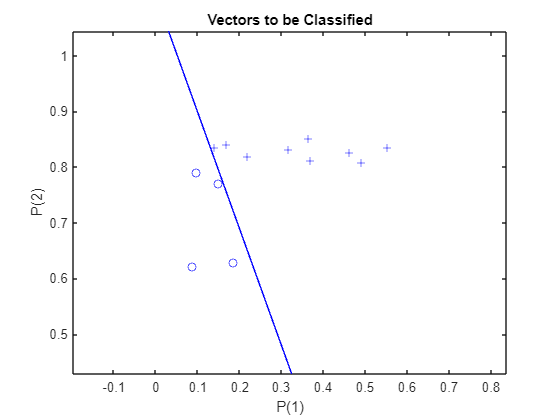

plotpv(P_full,T_full)
plotpc([w1 w2], b)